Fit, compare, analyze, and plot Experiment 1 behavioural models

projectDir = '/Users/foxxis/Desktop/HBI/exp1';
cd(projectDir);
addpath(projectDir);

addpath(fullfile(projectDir, 'src'));
addpath(fullfile(projectDir, 'src', 'models'));
addpath(fullfile(projectDir, 'src', 'plotting'));
addpath(fullfile(projectDir, 'src', 'r2_assignment'));

Load Experiment 1 data.

xlsx_file = '/Users/foxxis/Documents/social induction/experiment data/exp1/output100.xlsx';

raw_tbl = readtable(xlsx_file);
vars = {'d1','d2','d3','d4','d5','d6','d7','d8'};

Y = table2array(raw_tbl(:, vars));
N = size(Y, 1);

data = cell(N, 1);
for s = 1:N
    data{s} = struct('y', Y(s,:));
end

Prepare fitting output folder. results/fitting is the output location

fitDir = fullfile(projectDir, 'results', 'fitting');
if exist(fitDir, 'dir') ~= 7
    mkdir(fitDir);
end

outputs = struct();

Model fitting and HBI comparison. 

validate_cbm_data(data);

cbm_root = '/Users/foxxis/Documents/MATLAB/cbm-master';
addpath(genpath(cbm_root));

assert(exist('cbm_lap', 'file') == 2, ...
    'Cannot find cbm_lap. Check cbm_root in src/fitting/fit_models.m.');

cd results/fitting/

% The variance v controls the scale of the zero-mean Laplace prior on each
% parameter. A value of 6.25 is suggested by the CBM manual, which is 
% large enough to cover a wide range of parameters with no excessive
% penalty. As our model parameters are additionally transformed with exp()
% in the likelihood function, we use log(6.25) ≈ 1.8 to avoid overly
% dispersed initial parameter values. 
% Robustness checks were also run with alternative v values.
v = 1.8; 

% First, we should run cbm_lap, which fits every model to each subject data 
% separately (i.e. in a non-hierarchical fashion).
% Mentalizing model: one free parameter (log_ce)
prior_ment = struct('mean', zeros(1,1), 'variance', v);
cbm_lap(data, @mentalizing_model, prior_ment, 'lap_mentalizing.mat');

cbm_lap                                           14-Sep-2026 20:16:38
Number of samples: 101
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


% Level‑0 model: two free parameters (log_ce, log_n)
prior_vt = struct('mean', zeros(2,1), 'variance', v);
cbm_lap(data, @vt_model, prior_vt, 'lap_vt.mat');

cbm_lap                                           14-Sep-2026 20:16:40
Number of samples: 101
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
S


% Level‑1 (diversity weighted) model: three free parameters (log_ce, log_n, log_e)
prior_dw = struct('mean', zeros(3,1), 'variance', v);
cbm_lap(data, @dw_model, prior_dw, 'lap_dw.mat');

cbm_lap                                           14-Sep-2026 20:16:44
Number of samples: 101
Number of parameters: 3

Number of initializations: 21
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
S


% Level‑1 (knowledge weighted) model: two free parameters (log_ce, log_n)
prior_kw = struct('mean', zeros(2,1), 'variance', v);
cbm_lap(data, @kw_model, prior_kw, 'lap_kw.mat');

cbm_lap                                           14-Sep-2026 20:16:51
Number of samples: 101
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
S


% Baseline model: zero free parameters (uniform over responses)
prior_base = struct('mean', 0, 'variance', v);
cbm_lap(data, @baseline_model, prior_base, 'lap_baseline.mat');

cbm_lap                                           14-Sep-2026 20:16:54
Number of samples: 101
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


%Conduct hierarchical Bayesian inference using cbm_hbi
models = {@mentalizing_model, @vt_model, @dw_model, @kw_model, @baseline_model};
fcbm_maps = {'lap_mentalizing.mat', 'lap_vt.mat', 'lap_dw.mat', 'lap_kw.mat', 'lap_baseline.mat'};
hbi_file = 'hbi_compare.mat';
cbm_hbi(data, models, fcbm_maps, hbi_file);

cbm_hbi_hbi                                       14-Sep-2026 20:16:55
Running hierarchical bayesian inference (HBI)...

HBI has been initialized according to
	lap_mentalizing.mat [for model 1]
	lap_vt.mat [for model 2]
	lap_dw.mat [for model 3]
	lap_kw.mat [for model 4]
	lap_baseline.mat [for model 5]
 
Number of samples: 101
Number of models: 5
Iteration 01
Iteration 02
	model frequencies (percent)
	model 1: 16.9| model 2: 24.9| model 3: 21.6| model 4: 25.0| model 5: 11.6| 
                                                           dL:   24.42
                                                           dm:   74.99
                                                           dx:    0.48
Iteration 03
	model frequencies (percent)
	model 1: 16.7| model 2: 26.0| model 3: 19.2| model 4: 26.9| model 5: 11.2| 
                                                           dL:    2.57
                                             


%Load the saved file
S = load(hbi_file);
assert(isfield(S, 'cbm'), 'No cbm variable found in %s.', hbi_file);
cbm = S.cbm;
cbm.output

ans = struct with fields:
                     parameters: {5×1 cell}
                 responsibility: [101×5 double]
                     group_mean: {[1.2295]  [4.0034 -0.5581]  [-4.3404e-06 3.1034e-05 2.4990e-05]  [1.8242 0.6056]  [5.6721e-10]}
    group_hierarchical_errorbar: {[0.2310]  [0.3263 0.1277]  [0.1399 0.1399 0.1399]  [0.1146 0.1315]  [0.1921]}
                model_frequency: [0.1379 0.2509 2.1818e-04 0.4571 0.1539]
                exceedance_prob: [7.0000e-06 0.0069 0 0.9930 3.7000e-05]
      protected_exceedance_prob: [NaN NaN NaN NaN NaN]



cbm_frequency = cbm.output.model_frequency %cbm based model frequency calculated by summing each model's responsibility across all participants

cbm_frequency =     0.1379    0.2509    0.0002    0.4571    0.1539


% model frequency calculated by the proportion of participants best fit by each
% model
resp = cbm.output.responsibility;
[~, bestModelPerSubj] = max(resp, [], 2);
modelIDs = 1:5;
counts = histcounts(bestModelPerSubj, 0.5:1:5.5);
proportions = counts / numel(bestModelPerSubj);
modelNames = {'Mentalizing','VT','DW','KW','Baseline'};
freqTable = table(modelIDs(:), modelNames(:), counts(:), proportions(:), ...
    'VariableNames', {'ModelID','ModelName','Count','Proportion'});
disp(freqTable);

    ModelID       ModelName       Count    Proportion
    _______    _______________    _____    __________

       1       {'Mentalizing'}     12       0.11881  
       2       {'VT'         }     24       0.23762  
       3       {'DW'         }      0             0  
       4       {'KW'         }     47       0.46535  
       5       {'Baseline'   }     18       0.17822  




%parameter
group_mean_m = exp(cbm.output.group_mean{1});group_mean_m

group_mean_m = 3.4197

group_mean_mv = exp(cbm.output.group_mean{2});group_mean_mv

group_mean_mv =    54.7849    0.5723


group_mean_dw = exp(cbm.output.group_mean{3});group_mean_dw

group_mean_dw =     1.0000    1.0000    1.0000


group_mean_kw = exp(cbm.output.group_mean{4});group_mean_kw

group_mean_kw =     6.1980    1.8324


group_mean_b = exp(cbm.output.group_mean{5});group_mean_b

group_mean_b = 1.0000

responsibility = cbm.output.exceedance_prob

responsibility =     0.0000    0.0069         0    0.9930    0.0000



% Calculate proected exceedance probabilities by re-running under the (prior) null hypothesis
cbm_hbi_null(data,hbi_file)

cbm_hbi_hbi                                       14-Sep-2026 20:17:09
Running hierarchical bayesian inference (HBI)- null mode...

HBI has been initialized according to
	lap_mentalizing.mat [for model 1]
	lap_vt.mat [for model 2]
	lap_dw.mat [for model 3]
	lap_kw.mat [for model 4]
	lap_baseline.mat [for model 5]
 
Number of samples: 101
Number of models: 5
Iteration 01
Iteration 02
                                                           dL:    7.98
                                                           dx:    0.18
Iteration 03
                                                           dL:    0.35
                                                           dx:    0.05
Iteration 04
                                                           dL:    0.41
                                                           dx:    0.03
Iteration 05
                                                           dL:    0.36
       

ans = struct with fields:
        method: 'hbi'
         input: [1×1 struct]
       profile: [1×1 struct]
          math: [1×1 struct]
        output: [1×1 struct]
    exceedance: [1×1 struct]



% Load the corrected HBI results
S   = load(hbi_file, 'cbm');
cbm = S.cbm;

% Extract posterior quantities (for inspection)
pxp  = cbm.output.protected_exceedance_prob;
pxp

pxp =     0.0000    0.0069    0.0000    0.9930    0.0000


Compute R² metrics

cd(projectDir);

run_exp1_r2_assignment(projectDir, data, cbm);

Unrecognized function or variable 'data'.

Figures. 

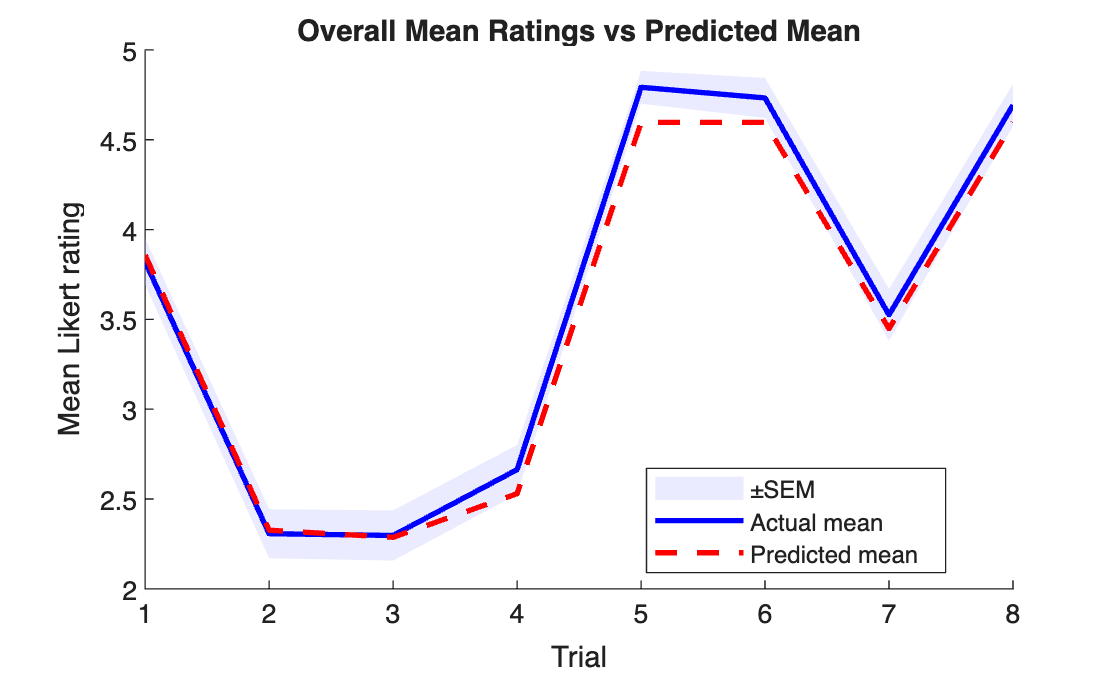

% -------- Generate summary plots --------
% Determine best model per subject (for plotting)
[~, bestModelPerSubj] = max(resp, [], 2);

% 1) Overall mean ratings vs predicted mean ratings
plot_overall_means(data, cbm, bestModelPerSubj);


% 2) Mean ratings by strategy group with predicted means
plot_choices_by_strategy(data, cbm, bestModelPerSubj);


% 3) Distributions of choices by strategy and trial with beta predictions
plot_choice_distribution_beta(data, cbm, bestModelPerSubj);

Robustness Check

cd /Users/foxxis/Desktop/HBI/exp1/results/fitting/

v = 5; 

% First, we should run cbm_lap, which fits every model to each subject data 
% separately (i.e. in a non-hierarchical fashion).
% Mentalizing model: one free parameter (log_ce)
prior_ment = struct('mean', zeros(1,1), 'variance', v);
cbm_lap(data, @mentalizing_model, prior_ment, 'lap_mentalizing_r.mat');

cbm_lap                                           14-Sep-2026 20:17:59
Number of samples: 101
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


% Level‑0 model: two free parameters (log_ce, log_n)
prior_vt = struct('mean', zeros(2,1), 'variance', v);
cbm_lap(data, @vt_model, prior_vt, 'lap_vt_r.mat');

cbm_lap                                           14-Sep-2026 20:18:01
Number of samples: 101
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
S


% Level‑1 (diversity weighted) model: three free parameters (log_ce, log_n, log_e)
prior_dw = struct('mean', zeros(3,1), 'variance', v);
cbm_lap(data, @dw_model, prior_dw, 'lap_dw_r.mat');

cbm_lap                                           14-Sep-2026 20:18:06
Number of samples: 101
Number of parameters: 3

Number of initializations: 21
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
S


% Level‑1 (knowledge weighted) model: two free parameters (log_ce, log_n)
prior_kw = struct('mean', zeros(2,1), 'variance', v);
cbm_lap(data, @kw_model, prior_kw, 'lap_kw_r.mat');

cbm_lap                                           14-Sep-2026 20:18:14
Number of samples: 101
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
--- This initialization was aborted (there might be a problem with the model)
--- The message of optimization routine is:
---    Z must be real and non-negative.
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject


% Baseline model: zero free parameters (uniform over responses)
prior_base = struct('mean', 0, 'variance', v);
cbm_lap(data, @baseline_model, prior_base, 'lap_baseline_r.mat');

cbm_lap                                           14-Sep-2026 20:18:19
Number of samples: 101
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


%Conduct hierarchical Bayesian inference using cbm_hbi
models = {@mentalizing_model, @vt_model, @dw_model, @kw_model, @baseline_model};
fcbm_maps = {'lap_mentalizing.mat', 'lap_vt.mat', 'lap_dw.mat', 'lap_kw.mat', 'lap_baseline.mat'};
hbi_file = 'hbi_compare_r.mat';
cbm_hbi(data, models, fcbm_maps, hbi_file);

cbm_hbi_hbi                                       14-Sep-2026 20:18:20
Running hierarchical bayesian inference (HBI)...

HBI has been initialized according to
	lap_mentalizing.mat [for model 1]
	lap_vt.mat [for model 2]
	lap_dw.mat [for model 3]
	lap_kw.mat [for model 4]
	lap_baseline.mat [for model 5]
 
Number of samples: 101
Number of models: 5
Iteration 01
Iteration 02
	model frequencies (percent)
	model 1: 16.9| model 2: 24.9| model 3: 21.6| model 4: 25.0| model 5: 11.6| 
                                                           dL:   24.42
                                                           dm:   74.99
                                                           dx:    0.48
Iteration 03
	model frequencies (percent)
	model 1: 16.7| model 2: 26.0| model 3: 19.2| model 4: 26.9| model 5: 11.2| 
                                                           dL:    2.57
                                             


%Load the saved file
S = load(hbi_file);
assert(isfield(S, 'cbm'), 'No cbm variable found in %s.', hbi_file);
cbm = S.cbm;
cbm.output

ans = struct with fields:
                     parameters: {5×1 cell}
                 responsibility: [101×5 double]
                     group_mean: {[1.2295]  [4.0034 -0.5581]  [-4.3404e-06 3.1034e-05 2.4990e-05]  [1.8242 0.6056]  [5.6721e-10]}
    group_hierarchical_errorbar: {[0.2310]  [0.3263 0.1277]  [0.1399 0.1399 0.1399]  [0.1146 0.1315]  [0.1921]}
                model_frequency: [0.1379 0.2509 2.1818e-04 0.4571 0.1539]
                exceedance_prob: [6.0000e-06 0.0069 0 0.9931 3.6000e-05]
      protected_exceedance_prob: [NaN NaN NaN NaN NaN]


model_frequency = cbm.output.model_frequency

model_frequency =     0.1379    0.2509    0.0002    0.4571    0.1539


group_mean_m = cbm.output.group_mean{1};group_mean_m

group_mean_m = 1.2295

group_mean_mv = cbm.output.group_mean{2};group_mean_mv

group_mean_mv =     4.0034   -0.5581


group_mean_dw = cbm.output.group_mean{3};group_mean_dw

group_mean_dw = 1.0e-04 *

   -0.0434    0.3103    0.2499


group_mean_kw = cbm.output.group_mean{4};group_mean_kw

group_mean_kw =     1.8242    0.6056


group_mean_b = cbm.output.group_mean{5};group_mean_b

group_mean_b = 5.6721e-10

responsibility = cbm.output.exceedance_prob

responsibility =     0.0000    0.0069         0    0.9931    0.0000



% Calculate proected exceedance probabilities by re-running under the (prior) null hypothesis
cbm_hbi_null(data,hbi_file)

cbm_hbi_hbi                                       14-Sep-2026 20:18:34
Running hierarchical bayesian inference (HBI)- null mode...

HBI has been initialized according to
	lap_mentalizing.mat [for model 1]
	lap_vt.mat [for model 2]
	lap_dw.mat [for model 3]
	lap_kw.mat [for model 4]
	lap_baseline.mat [for model 5]
 
Number of samples: 101
Number of models: 5
Iteration 01
Iteration 02
                                                           dL:    7.98
                                                           dx:    0.18
Iteration 03
                                                           dL:    0.35
                                                           dx:    0.05
Iteration 04
                                                           dL:    0.41
                                                           dx:    0.03
Iteration 05
                                                           dL:    0.36
       

ans = struct with fields:
        method: 'hbi'
         input: [1×1 struct]
       profile: [1×1 struct]
          math: [1×1 struct]
        output: [1×1 struct]
    exceedance: [1×1 struct]



% Load the corrected HBI results
S   = load(hbi_file, 'cbm');
cbm = S.cbm;

% Extract posterior quantities (for inspection)
pxp  = cbm.output.protected_exceedance_prob;
pxp

pxp =     0.0000    0.0069    0.0000    0.9930    0.0000


Local helper functions

function validate_cbm_data(data)
%VALIDATE_CBM_DATA Basic validation for CBM data cell arrays.

assert(iscell(data) && ~isempty(data), ...
    'Data must be a non-empty cell array of subject structs.');

assert(isstruct(data{1}) && isfield(data{1}, 'y'), ...
    'Each data cell must contain a struct with field y.');

M = numel(data{1}.y);
assert(M > 0, 'data{1}.y must contain at least one response.');

for s = 1:numel(data)
    assert(isstruct(data{s}) && isfield(data{s}, 'y'), ...
        'data{%d} must be a struct with field y.', s);
    assert(numel(data{s}.y) == M, ...
        'Subject %d has %d trials; expected %d.', s, numel(data{s}.y), M);
end
end
